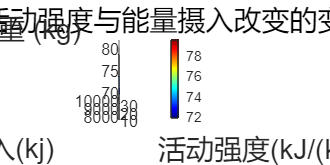

Day = 90;    %体重变化的天数
Exercise_Time = 1;  %每天运动的时间——小时
MET = 10:1:30;       %活动强度
Intake = 7524:100:9524;     %摄入的能量
Weight = 80;    %初始体重(以成年男性为例)-kg
C = 35000;      %每千克脂肪的能量
New_Weight = zeros(length(MET),length(Intake));%变化后的体重
for i =1:length(MET)
    for j = 1:length(Intake)
        Tmp_weight = zeros(1,Day+1);
        Tmp_weight = Weight;
        for D = 1:Day
            BMR = Tmp_weight(D)*4.2*24;%每天基础消耗的能量
            SDA = 0.1*BMR; %消化耗能
            Exercise = MET(i)*Tmp_weight(D);
            Change_Weight = (Intake(j)-(BMR+SDA+Exercise))/C;%
            Tmp_weight(D+1) = max(Tmp_weight(D)+Change_Weight,40);
        end
        New_Weight(i,j) = Tmp_weight(end);
    end
end
[X, Y] = meshgrid(MET, Intake);
figure('Position', [100, 100, 1200, 600]);
surf(X', Y', New_Weight, 'EdgeColor', 'none');
colormap(jet); 
colorbar;
xlabel('活动强度(kJ/(kg·h)', 'FontSize', 14);
ylabel('能量摄入(kj)', 'FontSize', 14);
zlabel('最终体重 (kg)', 'FontSize', 14);
title('90天内体重随活动强度与能量摄入改变的变化情况', 'FontSize', 14);